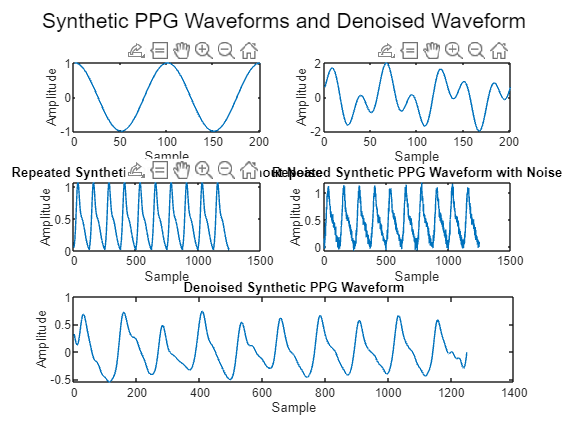

clc;
close all;
clear all;

% Step 1: Generate and Plot Simple Sinusoidal Waveform (Wave 1)
x = 0:pi/100:2*pi;
wave_1 = cos(x*2);

% Step 2: Simulate PPG Waveforms Using Sinusoids (Wave 2)
wave_2 = cos(x*3) + cos(x*7 - 2);

% Step 3: Generate Synthetic PPG Waveforms
Duration = 1;
Fs = 125; % Sampling Frequency
a = [0.82, 0.4];
mu = [-pi/2, 0];
sigma = [0.6, 1.2];
Samples = Fs * Duration;
V_angle = 2 * pi / Samples;
angle = (-pi + V_angle) : V_angle : pi;
y1 = a(1) * exp(-(((angle - mu(1)) / sigma(1)).^2) / 2);
y2 = a(2) * exp(-(((angle - mu(2)) / sigma(2)).^2) / 2);
y = y1 + y2;

% Step 4: Add Baseline Wander and Noise to Synthetic PPG Waveforms
baseline_amplitude = 0.1; % Amplitude of baseline wander
baseline_frequency = 0.5; % Frequency of baseline wander (in Hz)

t = linspace(0, Duration, Samples);
baseline_wander = baseline_amplitude * sin(2 * pi * baseline_frequency * t);

repetitions = 10;
y_repeated = zeros(Samples * repetitions, 1);
y_repeated_with_noise = zeros(Samples * repetitions, 1);

for i = 1:repetitions
    % Combine baseline wander with the PPG waveform
    y_with_baseline = y + baseline_wander;
    % Combine noise with the PPG waveform
    noise = 0.05 * randn(Samples, 1);
    y_with_noise = y + baseline_wander + noise';
    
    % Add the waveform to the repeated waveform
    y_repeated((i - 1) * Samples + 1 : i * Samples) = y_with_baseline;
    y_repeated_with_noise((i - 1) * Samples + 1 : i * Samples) = y_with_noise;
end

% Step 5: Denoise the PPG waveform using a low-pass filter
cutoff_frequency = 10; % Cutoff frequency of the low-pass filter (in Hz)
% [b, a] = cheby2(6, cutoff_frequency / (Fs / 2), 'low');
y_denoised = bandpass(y_repeated_with_noise, [0.6 5], 125);

% Plotting all waveforms using subplots
figure;

% Plot wave_1
subplot(3, 2, 1);
plot(wave_1);
xlabel('Sample');
ylabel('Amplitude');
title('Wave 1');

% Plot wave_2
subplot(3, 2, 2);
plot(wave_2);
xlabel('Sample');
ylabel('Amplitude');
title('Wave 2');

% Plot y_repeated
subplot(3, 2, 3);
plot(y_repeated);
xlabel('Sample');
ylabel('Amplitude');
title('Repeated Synthetic PPG Waveform without Noise');

% Plot y_repeated_with_noise
subplot(3, 2, 4);
plot(y_repeated_with_noise);
xlabel('Sample');
ylabel('Amplitude');
title('Repeated Synthetic PPG Waveform with Noise');

% Plot denoised PPG waveform
subplot(3, 2, [5, 6]);
plot(y_denoised);
xlabel('Sample');
ylabel('Amplitude');
title('Denoised Synthetic PPG Waveform');

% Adjust subplot spacing
sgtitle('Synthetic PPG Waveforms and Denoised Waveform');